# Homework 2 (60pt)

*Type your NAME (first, last) and ID below*

Boxuan Zhang 95535906

## Homework instructions:

- Write your **name** and **student ID** in the above section.

- Make sure you have downloaded all related files from Canvas.

- Write ALL answers and your MATLAB code in this livescript file, make sure you write your code in the code block and test it before submission.

- Usually you should only submit this livescript (.mlx file) with all your answers and code. However, if you have additional .m files, please make sure to put them in the same folder.  

- Rename this livescript as "***Math9_HW2_(your name)_(your ID).mlx***" before submission!

- You are responsible for checking UCI email and course Canvas page regularly for potential updates.

**Note:** Throughout this homework, please define the functions as ***in-script***, i.e. at the end of this live script file. Do not define functions in additional .m files. 

## Problem 1. Sum of Series (9pt)

**(2pt)** 1. First, please define a function named "`calc_sum"` at **THE END** of this live script, whose inputs are function handle $f$ and the total number of terms for summation $k$ , and output the value of sums $S_k =\sum_{n=1}^k f\left(n\right)=f\left(1\right)+f\left(2\right)+\ldotp \ldotp \ldotp +f\left(k\right)$.

In mathematics, we have the following two interesting formulas about $\pi$:

a. $\sum_{n=1}^{+\infty } \frac{1}{n^2 }=\frac{\pi^2 }{6}$

b. $\sum_{n=1}^{+\infty } \frac{{\left(-1\right)}^{n+1} }{2n-1}=\frac{\pi }{4}$

Follow the insturctions below to validate these formulas:

**(1pt)** 2. Define the variable $k$ by inserting numerical slider from 100 to 10000 with step 100  (suppress the output of this line).

k = 10000;

**(3pt) **3. Using the function "`calc_sum`" you defined, calculate the sum of first $k$ terms, i.e. $\sum_{n=1}^k \frac{1}{n^2 }$ and $\sum_{n=1}^k \frac{{\left(-1\right)}^{n+1} }{2n-1}$ respectively, and store them as two variables (also suppress the outputs for this step). 

% a
f = @(n) 1/n^2;
sum1 = calc_sum(k, f);
% b
f = @(n) (-1)^(n+1)/(2*n-1);
sum2 = calc_sum(k, f);

**(2pt) **4. Calculate the absolute errors between the first-$k$-term sums with their corresponding limits (right hand sides of the formulas above). Do not suppress the output in this step.

abs_err1 = abs(sum1 - pi^2 / 6)

abs_err1 =      9.999500016122376e-05


abs_err2 = abs(sum2 - pi/4)

abs_err2 =      2.499999993965663e-05


**(1pt) **5. When increasing $k$, what change do you observe? ***Write your answer here: ***

***With k increases, the absolute error between two k-term sums decreases.***

## Problem 2. Functions for Numerical Integral (9pt)

Similar to the examples shown in the lecture,  define two functions at **THE END** of this live script "`integral_mid(f, a, b, n)" and "integral_trap(f, a, b, n)" `that use **mid-point **and** trapezoidal** formulas to approximate$\int_a^b f\left(x\right)\textrm{dx}$ respectively (for formulas, see homework 1). The meanings of inputs are the same as in the lecture examples.

**(6pt) **1. Call your functions in the code block below to approximate $\int_1^5 \left(3x+e^{-x^3 } \right)\textrm{dx}$ (pick the n as you like -- as long as you think it is reasonable).

a = 1;
b = 5;
n = 1000;
f = @(x) 3.*x + exp(-x.^3);
mid = integral_mid(f,a,b,n)

mid =   36.085467593668291


trap = integral_trap(f,a,b,n)

trap =   36.085469800950094


**(3pt)** 2. Check the answer by calling the MATLAB function `integral`. The three answers should be very close.

integral(f, a ,b)

ans =   36.085468329429574


## Problem 3. Padovan Sequence (11pt)

Padovan sequence is defined by the recursive formula $a_n =a_{n-2} +a_{n-3} ,\;a_0 =a_1 ={\;a}_2 =1\ldotp$

Please define two **in-script** functions (at **THE END** of this live script) "`pad1(n)"` and "`pad2(k)"`, such that: 

**(3pt) **1. "`pad1"` outputs the row vector storing the first **n** terms in Padovan sequence. 

**(4pt) **2. "`pad2"` outputs the row vector storing all terms in Padovan sequence that are smaller than **k**.

In this problem, you don't need to consider the algorithm efficiency or the robustness issues -- don't worry about running the code with super large n and k, just focus on the corretness of codes and outputs. 

When testing the code, you should set n and k as "reasonable integers" (between 1 and 1000). 

**(1pt) **3. Check your codes by calling the two functions as follows and run.

**(3pt) **4. Write your code in the code box below (do not define any new functions) to: (1) define variable **k **using a numeric slider with Min = 10, Max = 100, Step = 1, and (2) check if pad2(k)'s total number of elements is greater than k/2. If so, display "The total number of elements is less than half of the input value." , otherwise display "The total number of elements is greater or equal to half of the input value."

pad1(10)

ans =      1     1     1     2     2     3     4     5     7     9


pad2(100)

ans =      1     1     1     2     2     3     4     5     7     9    12    16    21    28    37    49    65    86



% 4. write your code below
k = 10;
if length(pad2(k)) > k/2
    disp('The total number of elements is less than half of the input value')
else
    disp('The total number of elements is greater or equal to half of the input value')
end

The total number of elements is less than half of the input value


## Problem 4. Quantifying Approximation Errors of Different Numerical Integral Formulas (16pt)

SImilar to the left-end formula example in lecture, in this problem we investigate and compare the convergence rate of approximation errors in right-end, mid-point and trapezoidal formulas. Write codes in the code block below by following the instructions:

**(1pt) **1. Define row vector `N` from 10 to 500 with stepsize 20.

N = 10:20:500;

**(1pt) **2. Initialize **matrix** "`err"` with three rows, the same number of columns as N, and all elements as zeros.

err = zeros(3,length(N));

**(2pt) **3. Define three **in-script** functions "`integral_right(f,a,b,n)", "integral_mid(f, a, b, n)" and "integral_trap(f, a, b, n)" `that use **right-end, mid-point **and** trapezoidal** formulas to approximate$\int_a^b f\left(x\right)\textrm{dx}$ respectively (The meanings of the input and ouput are the same with what we introduced in the lectures and homeworks before). `(integral_mid and integral_trap have been defined in Problem 2, the mid-point and trapezoidal formulas are provided in Homework 1)`

**(7pt) **4. Use loops to modify the values in the matrix "`err"`, such that: 

1) the 1st, 2nd, and 3rd rows are correspond to the errors of using the right-end formula, the mid-point formula, and the trapezoidal formula, respectively;

2) the i-th column stores the **absolute errors **of approximating$\int_{\frac{\pi }{2}}^{\pi } \cos \left(x\right)\textrm{dx}=-1$ using the three formulas with `N(i)` partition intervals respectively.

f = @(x) cos(x);
a = pi/2;
b = pi;

exact = integral(f, pi/2, pi);
for i = 1:length(N)
    n = N(i);
    err(1,i) = abs(integral_right(f,a,b,n) - exact);
    err(2,i) = abs(integral_mid(f,a,b,n) - exact);
    err(3,i) = abs(integral_trap(f,a,b,n) - exact);
end
err

err =    0.076482802694102   0.025951465275319   0.015625715211671   0.011178010806899   0.008701261346111   0.007122990125334   0.006029357632129   0.005226849216687   0.004612874419607   0.004127978782630   0.003735328738399   0.003410887725203   0.003138302783291   0.002906061553401   0.002705824619814   0.002531402849187   0.002378106309322   0.002242316247851   0.002121195789897   0.002012489591789   0.001914382095088   0.001825395313450   0.001744313860389   0.001670129108195   0.001601997014874
   0.001028824142709   0.000114240667270   0.000041124535493   0.000020981610028   0.000012692505260   0.000008496610797   0.000006083361951   0.000004569275912   0.000003557392221   0.000002847883217   0.000002331259568   0.000001943450266   0.000001644935961   0.000001410267225   0.000001222455020   0.000001069807036   0.000000944062875   0.000000839252568   0.000000750974677   0.000000675926547   0.000000611590858   0.000000556021737   0.000000507695880   0.000000465407029   0.00000042

**hint:** the value on row 2, column 3 should be the error of using the mid-point formula with `n=N(3)`

**(1pt) **5. Run the codes provided to plot figures.

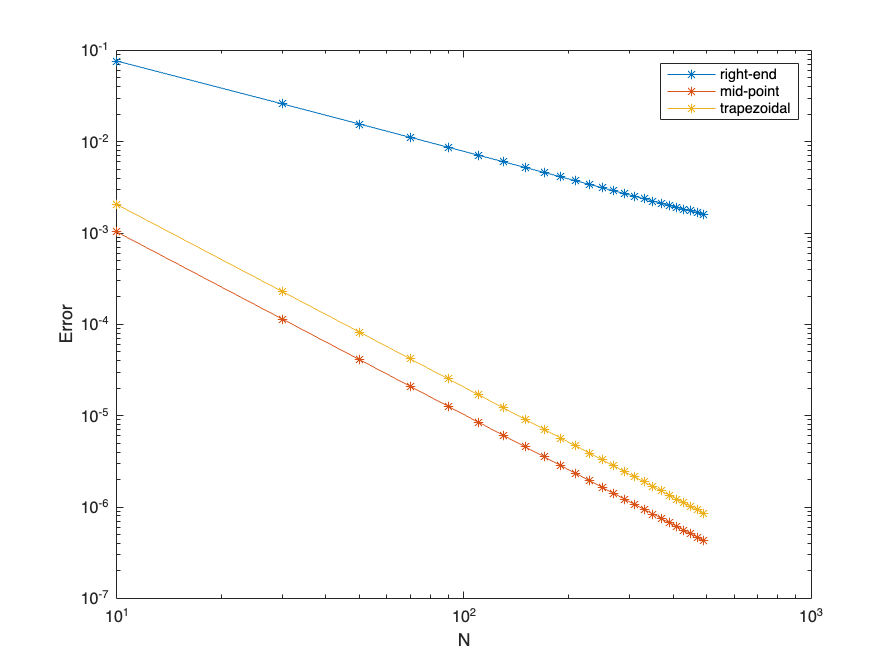

% to correctly runn the plot codes below, make sure "err" is a 3-by-length(N) matrix
loglog(N,err','*-')
legend('right-end','mid-point','trapezoidal')
xlabel('N')
ylabel('Error')

**(3pt) **6. In principle, you should see three lines. Following the example in lecture, use the polyfit function to see the slopes/intercepts of three lines (**hint:** you should fit between vectors log(N) and log(err(i,:)), i = 1,2,3 ). 

% polyfit codes and output here
for i = 1:3
    polyfit(log(N), log(err(i,:)),1)
end

ans =   -0.995327495042619  -0.268725242083649


ans =   -2.000105364796720  -2.274302295519865


ans =   -2.000060213577775  -1.581406282854070


**(1pt) **7. From the explorations above, what conclusion can you draw about the convergence rates of three approximation errors as n increases? i.e. 1) how will n affect absolute errors **quantitatively** in three formulas? 2) with the same n, which formula tends to have the best approximation?

***With n increases, the convergence rates of three approximation errors decrease. The absolute error decreases with the increment of n. With the same n, the second formula tends to have best approximation since the approximation error will decrease more with the increment of n.***

## Problem 5. Searching a Specific Element in a Sorted Vector (15pt)

The following (adapted from Wikipedia) gives a pseudo-code (not executable but have the basic logic) for searching a sorted vector $A$ for a specific element $T$:

===============================================

Given an array $A$ of n elements with values or records $A_1$, ..., $A_n$ and the target value $T$. The following steps use binary search to find the index of $T$ in $A$:

1. Set $L$ to 1 and $R$ to n.

2. If $L>R$, the search terminates as unsuccessful. 

3. Set $m$ (the position of the middle element) to the floor of $\frac{\left(L+R\right)}{2}$. (**hint:** check out the floor function in MATLAB [here](https://www.mathworks.com/help/matlab/ref/floor.html?s_tid=doc_ta)!)

4. If $A_m <T$, then set $L$ to $\left(m+1\right)$ and go to step 2.

5. If $A_m >T$, then set $R$ to $\left(m-1\right)$ and go to step 2.

6. If $A_m =T$, then the search is done, return $m$.

===============================================

Understand the above pseudo-code and answer the following questions (or write codes in the code block below):

**(1pt) **1. What are the input and output of this pseudo-code?

** Input is the target value, output is the index of the target value if the value exists in the array, otherwise, the output is the message "Target value not found!"**

**(2pt) **2. Generate a 1-by-50 row vector "`A_random"` of uniformly distributed random integers from the sample interval `[0,500]` using function `randi`. (**hint:** check out the help page of "`randi"` [here](https://www.mathworks.com/help/matlab/ref/randi.html?s_tid=doc_ta&requestedDomain=).)

% write your code here
A_random = [randi([0,500],1,50)]

A_random =    227    71   244    57   338   402    49   363   315   411   178   288   322   188   238   443   401   437    57    81   476    66    85   489   344     5   266   248   155   336   189   422   402   203   202   468    50    53   285   213     9   482   352    41   448   288   402    13   203   138


**(1pt) **3. Use function "`unique"` in MATLAB (check out its help page [here](https://www.mathworks.com/help/matlab/ref/double.unique.html?requestedDomain=us)) to select and sort the unique values of "`A_random",` name the new vector as `A`.

% write your code here
A = unique(A_random)

A =      5     9    13    41    49    50    53    57    66    71    81    85   138   155   178   188   189   202   203   213   227   238   244   248   266   285   288   315   322   336   338   344   352   363   401   402   411   422   437   443   448   468   476   482   489


**(1pt) **4. Are "`A_random"` and "`A"` always have the same number of elements? Why?

Because the random will change the elements in the A_random in every runing, also the unique function is to select the number without repition and there exists some repition in the A_random, so A will not always have the same number of elements with A_random

**(7pt) **5. Define an **in-script** function "`find_index()"` based on the above pseudo-code, and test your function with different $T$ using the same $A$ you obtained in the part 3.

Give one example that the Target value $T$ has been found successfully.

% write your code here
T = A(7);
find_index(A,T)

     7



**(1pt) 6**. What will happen if the target value $T$ is not in $A$? Write your answer here: ** It will not output the index and it may output some error message.**

**(2pt) 7**. Can you improve your function so that it returns a message "Target value not found!" when $T$ is not in $A$? 

**There is a disp function to output the message at the end of funcrtion, the function will return the index and finish the whole function if we find the target value. However, if we can not find the target value after the loop, the function will output the message.**

not_T = 1000;
find_index(A,not_T)

Target value not found!


## **Reference and Acknowledgement**

*You may list all the materials you referred to (including online materials and papers) and acknowledge the people who helped you in this section.*

## **Other Comments (optional)**

*You are welcome to leave your course-related comments here (lecture, homework, discussion session, etc.), you can also leave your comments in the Ed discussion panel or via email.*

## Define all the functions below

% calc_sum function
function sum = calc_sum(k, f)
    sum = 0;
    for x = 1:k
        sum = sum + f(x);
    end
end


% integral_mid function
function mid = integral_mid(f,a,b,n)
    h = (b-a)/n;
    x = a:h:b;
    mid_point = (x(1:end-1) + x(2:end)) / 2;
    mid = h*sum(f(mid_point));
end


% integral_trap function
function trap = integral_trap(f,a,b,n)
    h = (b-a)/n;
    x = a:h:b;
    trap1 = (f(x(1))+f(x(end))) / 2;
    trap2 = sum(f(x(2:end-1)));
    trap = h*(trap1 + trap2);
end


% pad1(n) function
function out = pad1(n)
    out = zeros(1,n);
    out(1:3) = 1;
    for i = 4:n
        out(i) = out(i-2) + out(i-3);
    end
end


% pad2(k) function
function out = pad2(k)
row = [1,1,1];
    i = 4;
    while true
        next = row(i-2) + row(i-3);
        if next >= k
            break;
        end
        row(i) = next;
        i = i+1;
    end
    out = row;
end


% function integral_right
function right = integral_right(f,a,b,n)
    h = (b - a) / n;
    x = a:h:b;
    y = f(x);
    right = h*sum(y(2:end));
end


% find_index function
function find_index(A, T)
    L = 1;
    R = length(A);
    while L <= R
        m =  floor((R+L)/2);
        if A(m) == T
            disp(m) 
            return
        end
        if A(m) < T
            L = m+1;
        elseif A(m) > T
            R = m-1;
        end
    end
    disp('Target value not found!')
end